Highly-simplified program for simulating an epidemic.

- S = Susceptible

- I = Infected

- R = Recovered

- L = Lost

- LPD = Lost (Per Day)

All time measured in days.

clear

S(1)=7e6; %initial susceptible population
I(1)=1; %initial infected population
R(1)=6e5; %initial recovered population

r=3e-8; %transmission rate
a=5e-2; %recovery rate
b=a*1e-2; %mortality rate

dt=1; %timestep
tMax=60; %simulation time
t=0:dt:tMax; %time vector

for i=1:tMax/dt
    dSodt(i+1)=-r*S(i)*I(i);
    S(i+1)=S(i)+dSodt(i+1)*dt;
    
    dRodt(i+1)=a*I(i);
    R(i+1)=R(i)+dRodt(i+1)*dt;
    
    dIodt(i+1)=-dSodt(i+1)-dRodt(i+1)-b*I(i);
    I(i+1)=I(i)+dIodt(i+1)*dt;
end

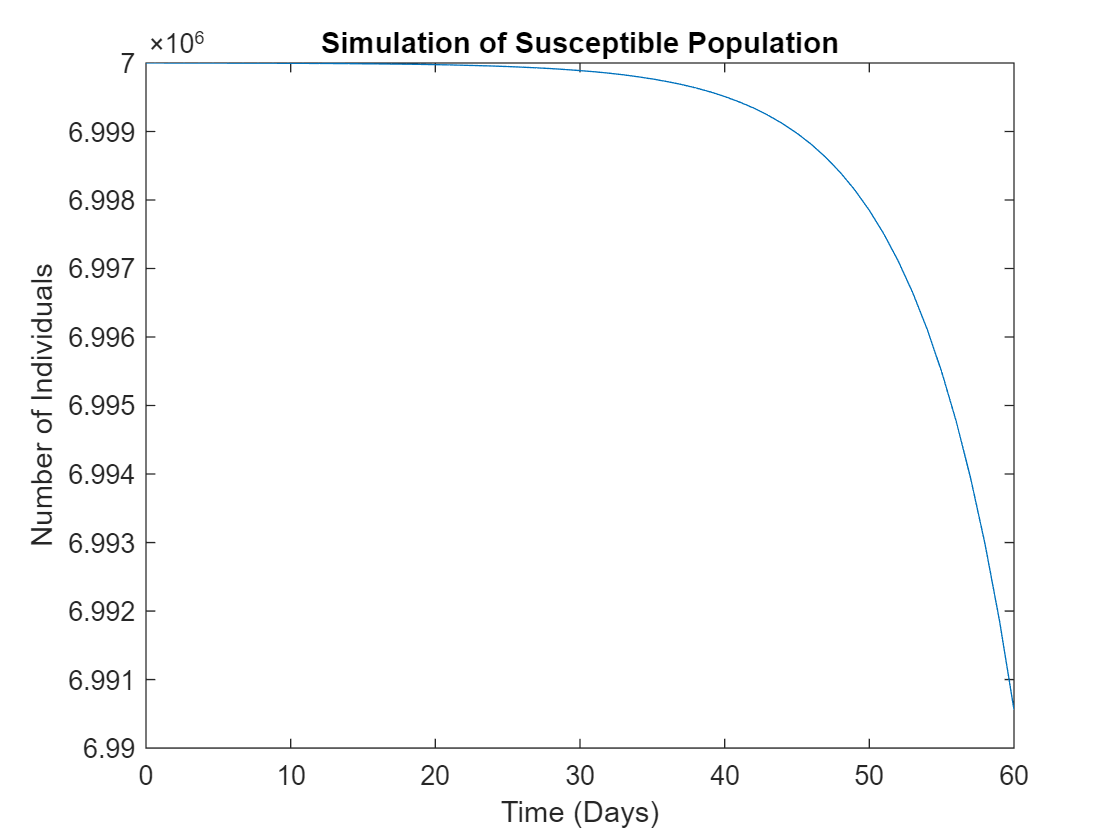

plot(t,S)
title('Simulation of Susceptible Population')
ylabel('Number of Individuals')
xlabel('Time (Days)')

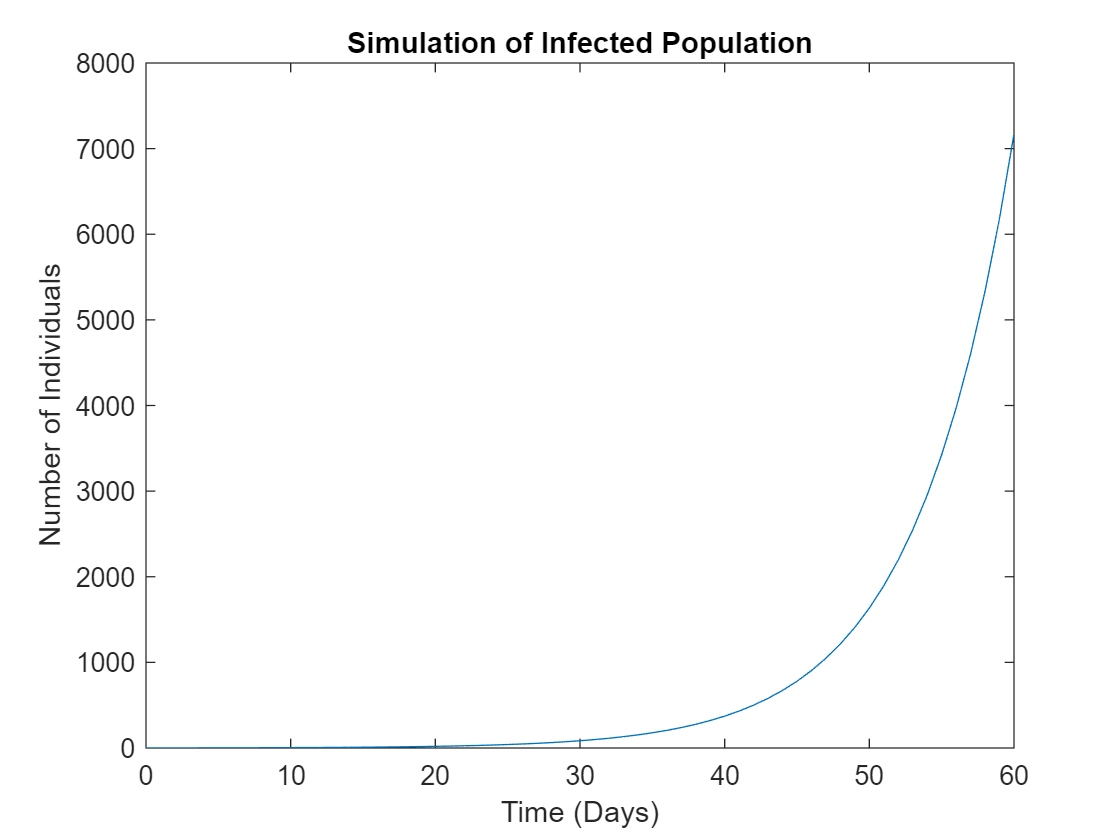

plot(t,I)
title('Simulation of Infected Population')
ylabel('Number of Individuals')
xlabel('Time (Days)')

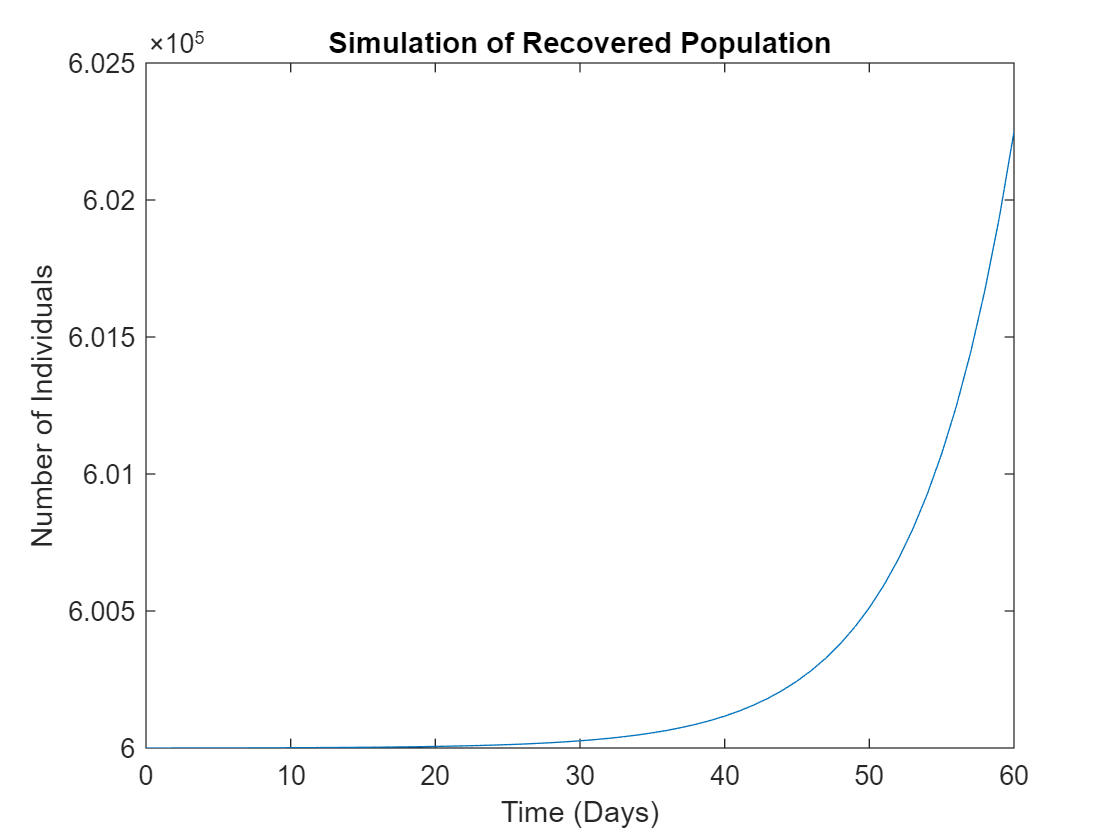

plot(t,R)
title('Simulation of Recovered Population')
ylabel('Number of Individuals')
xlabel('Time (Days)')

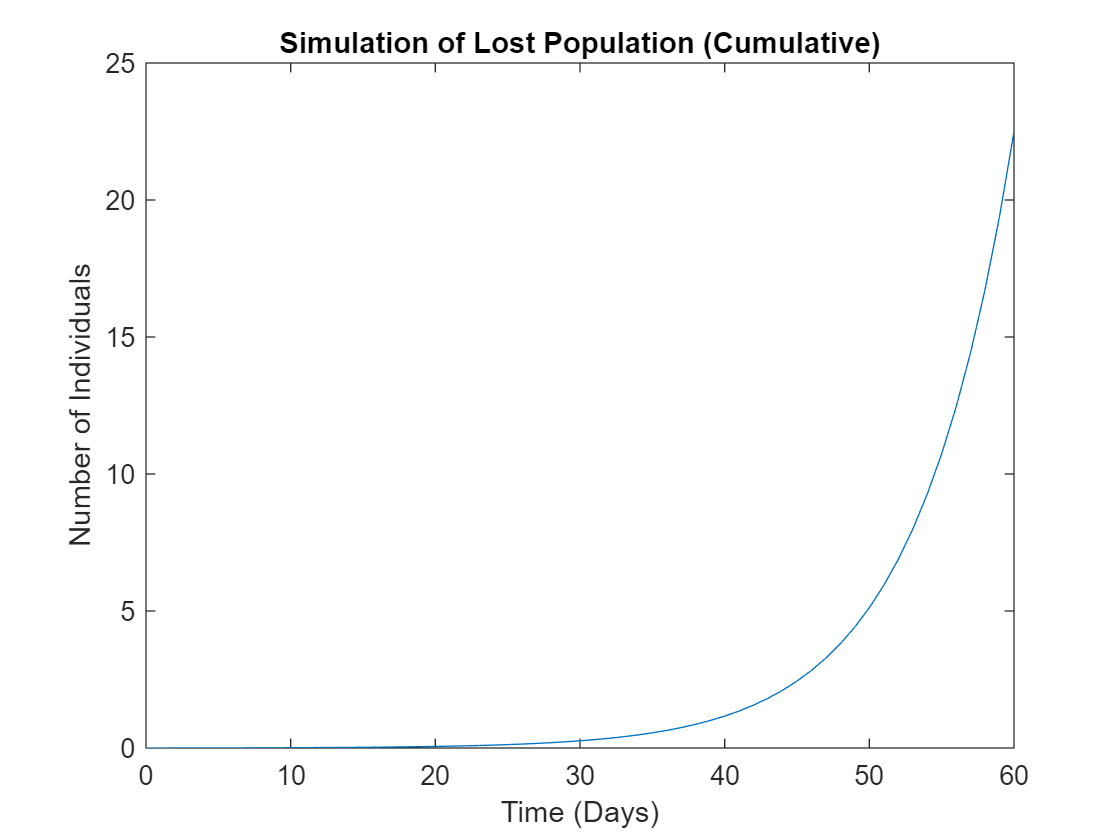

L=S(1)+I(1)+R(1)-S-I-R;

plot(t,L)
title('Simulation of Lost Population (Cumulative)')
ylabel('Number of Individuals')
xlabel('Time (Days)')

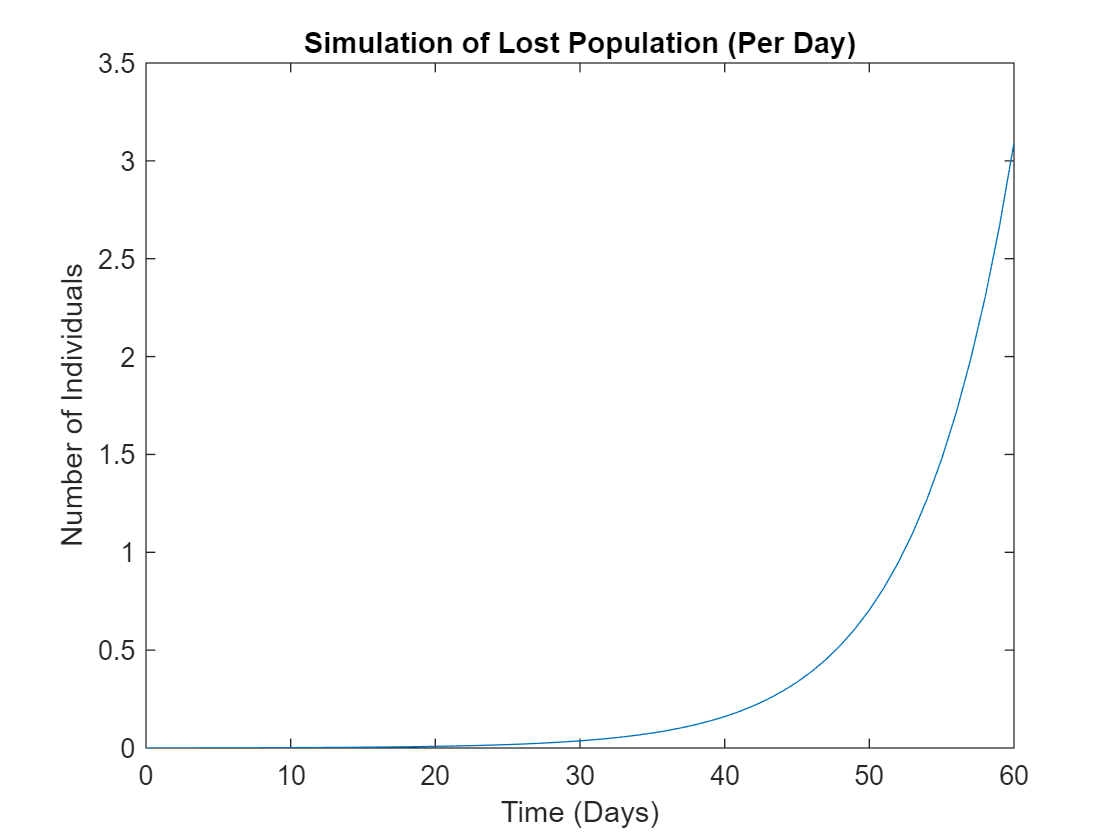

LPD(1)=L(1);
for i=1:tMax/dt
    LPD(i+1)=L(i+1)-L(i);
end

plot(t,LPD)
title('Simulation of Lost Population (Per Day)')
ylabel('Number of Individuals')
xlabel('Time (Days)')